clc
clear
disp("Initilization Procedure")

Initilization Procedure


model.Parameters
param = control.calculateOperatingPoint(param);

Calculate Operating Point for T_a = 293.150000 [K]

param = model.calculateModel(param);

Calculate bilinear model matrices
Calculate linearisation decoupled
Calculate linearisation coupled
Testing controlability
Testing T_ref


param = model.calculateWDelta(param,0);

## Three-step with alpha = 0


$$\Delta=\delta \textbf{I}, \delta\in[-1,1]$$


param = control.DesignProcedureSOF(param,0,{[-1,1]},0);

Evaluation of design procedure for three-step SOF 
Eigenvalues of the decoupled systems are all negative 


ans =   -3.5774 + 0.0000i  -0.2298 + 0.4800i  -0.2298 - 0.4800i  -3.6376 + 0.0000i  -0.2189 + 0.4980i  -0.2189 - 0.4980i  -3.5293 + 0.0000i  -0.2538 + 0.4487i  -0.2538 - 0.4487i  -3.5281 + 0.0000i  -0.2544 + 0.4597i  -0.2544 - 0.4597i


Eigenvalues of the coupled systems are all negative 


ans =   -3.1670 + 0.0000i  -2.8564 + 0.0000i  -2.7798 + 0.0000i  -2.4744 + 0.0000i  -0.4618 + 0.6079i  -0.4618 - 0.6079i  -0.5968 + 0.7039i  -0.5968 - 0.7039i  -0.6151 + 0.6228i  -0.6151 - 0.6228i  -0.7807 + 0.5618i  -0.7807 - 0.5618i


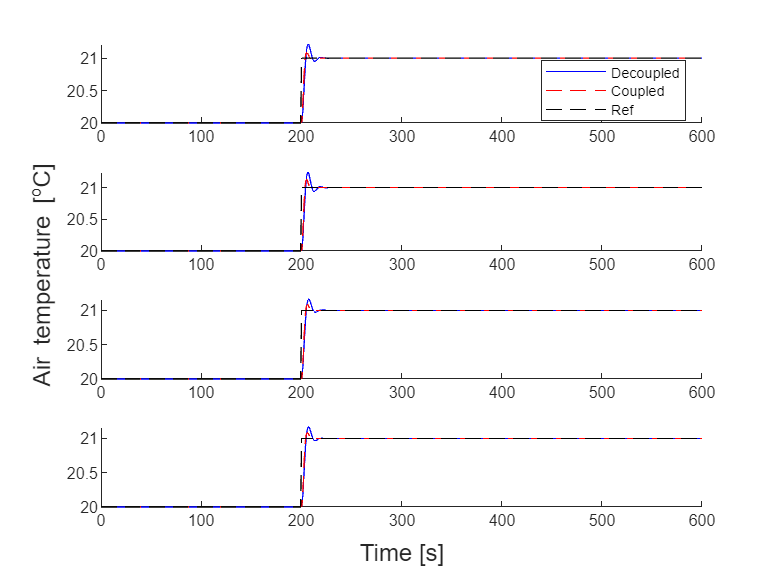

util.SimulateLinearStep(param,"Examination_Output_Feedback_alpha0",0);

## Three-step with alpha = 0.5


$$\Delta=\delta \textbf{I}, \delta\in[-1,1]$$


param = control.DesignProcedureSOF(param,0,{[-1,1]},0.5);

Evaluation of design procedure for three-step SOF 
Eigenvalues of the decoupled systems are all negative 


ans =    -4.0059   -0.0311   -0.0000   -4.0442   -0.0312   -0.0000   -4.0059   -0.0311   -0.0000   -4.0058   -0.0311   -0.0000


Eigenvalues of the coupled systems are all negative 


ans =    -4.0442   -4.0059   -4.0059   -4.0058   -0.0311   -0.0311   -0.0311   -0.0312   -0.0000   -0.0000   -0.0000   -0.0000


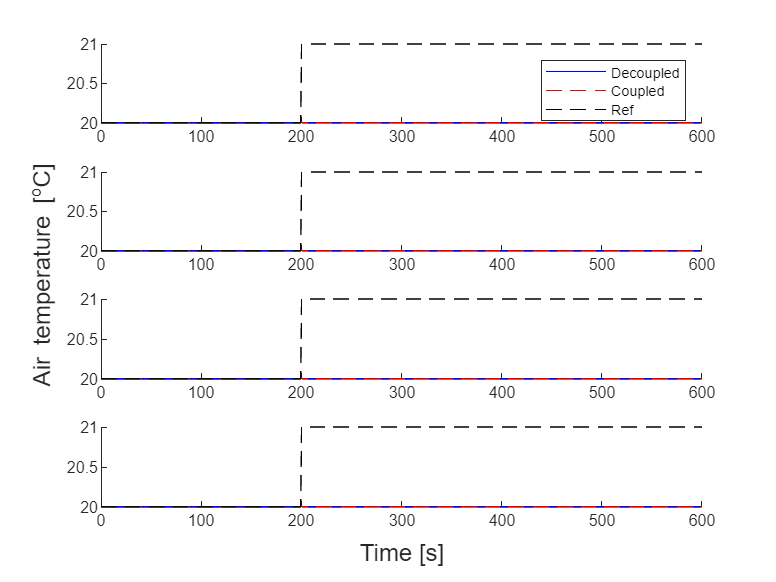

util.SimulateLinearStep(param,"Examination_Output_Feedback_alpha",0);

## ILMI algorithm


$$\Delta=\delta \textbf{I}, \delta\in[-1,1]$$


param = control.DesignProcedureSOF_ILMI(param,0,{[-1,1]});

ans = 0.1675

ans = -0.0874

Evaluation of design procedure for ILMI SOF 
Solved the problem in 2 iterations
The solution had alpha: 0.167480 
The solution had alpha: -0.087372 
Eigenvalues of the decoupled systems are all negative 


ans =    -3.5386   -0.4112   -0.0872   -3.5731   -0.3998   -0.1025   -3.5264   -0.3993   -0.1112   -3.5092   -0.4261   -0.1015


Eigenvalues of the coupled systems are all negative 


ans =   -3.0458 + 0.0000i  -2.5568 + 0.0000i  -2.3891 + 0.0000i  -0.9089 + 0.0000i  -1.9714 + 0.2443i  -1.9714 - 0.2443i  -1.3958 + 0.0000i  -1.5860 + 0.0000i  -0.0800 + 0.0000i  -0.0980 + 0.0000i  -0.0920 + 0.0000i  -0.0910 + 0.0000i


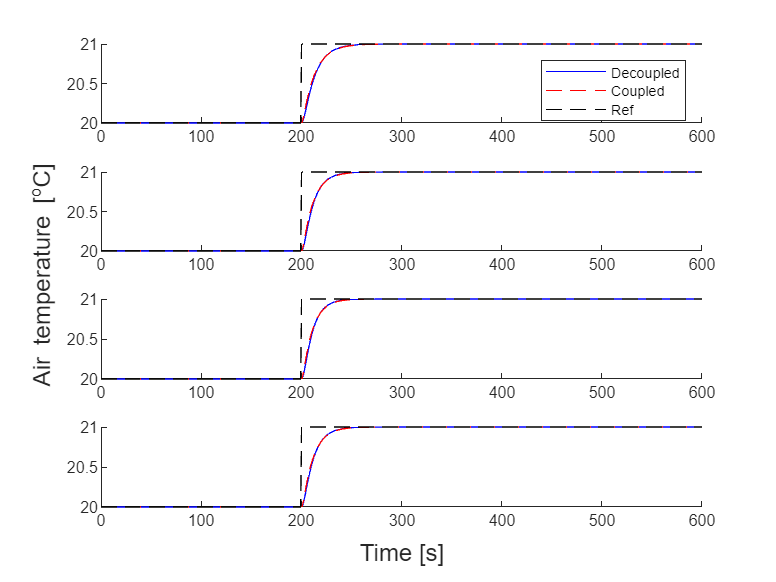

util.SimulateLinearStep(param,"Examination_Output_Feedback_ILMI",0);